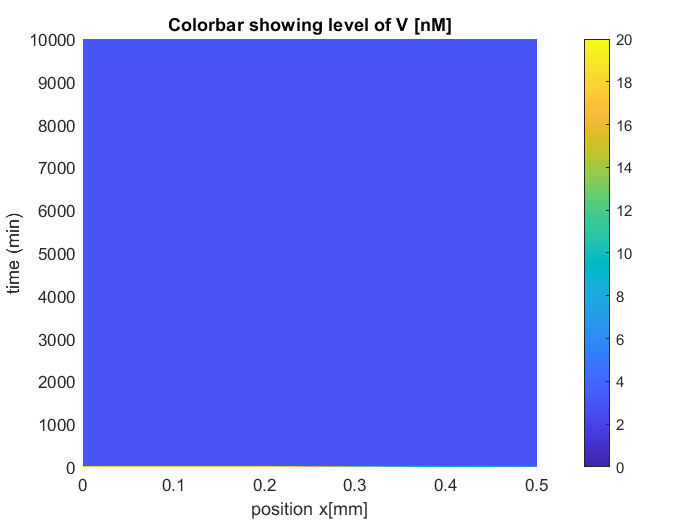


m = 0;
%Domain length
L=0.5;
%Standard deviation of the noise
sigma=1;

mu=5;

g=15;
A0B=25;

x_divs=400;
x = linspace(0,0.5,x_divs); % space
t_divs=500;
t_max=10000;
t = linspace(1,t_max,t_divs); % time
A=100; B=10; C=0.5;
sol = pdepe(m,@pde_fn_pde,@pde_fn_ic,@pde_fn_bc,x,t,[],A,B,C,g,A0B);
u1 = sol(:,:,1);
u2 = sol(:,:,2);
distance=sqrt( mean( (u1(1,:)-u1(t_divs,:)).^2 + (u2(1,:)-u2(t_divs,:)).^2 )  );

%The plotting stuff
c=u1 ;
surf(x,t,u1), colormap default,shading interp,caxis([0,20]), 
view([0.4 90.0])
colorbar
xlabel('position x[mm]')
ylabel('time (min)')
title('Colorbar showing level of V [nM]')


% The display stuff
disp("Time taken to achieve stable state is ="+time_for_ss(u1,x_divs,t_divs,t_max)+" mins, distance = "+ distance)

Time taken to achieve stable state is =40 mins, distance = 54.9681


%The comparison code for steady state time ( this takes time by the way ) 
% g_A = 10; 
g_B = 10;   

% Hills function threshold :
% A0B = 10;
B0A = 2;
g=15;
A0B=3;
g_divs=10;
g_array=linspace(0.5*g,g,g_divs);
A0B_divs=15;
A0B_array=linspace(0.1*A0B,A0B,A0B_divs);
%Number of samples to take 
r=4;
samplings=zeros(1,r);
%time array initialised
time_array=zeros(g_divs,A0B_divs);
cv_array=zeros(g_divs,A0B_divs);
for i=1:g_divs-1
    for j=1:A0B_divs
        for k=1:r
            sol = pdepe(m,@pde_fn_pde,@pde_fn_ic,@pde_fn_bc,x,t,[],A,B,C,g_array(i),A0B_array(j));
            u = sol(:,:,1);
            samplings(k)=time_for_ss(u,x_divs,t_divs,t_max);
            
          
        end
        value=log(mean(samplings)/100);
        cv_array(i,j)=std(samplings)/mean(samplings);
        time_array(i,j)=value;
        
    end
end

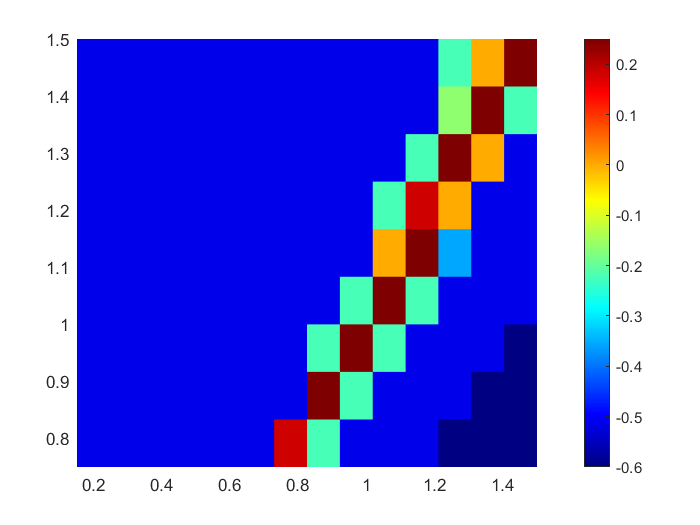

c=time_array ;
g_array=g_array./g_B;
A0B_array=A0B_array./B0A;
surf(A0B_array,g_array,time_array,'EdgeColor','none'), colormap jet,grid off,caxis([-0.6,0.25]), 
view([0.4 90.0])
ylim([min(g_array) max(g_array)])
xlim([min(A0B_array) max(A0B_array)])
colorbar

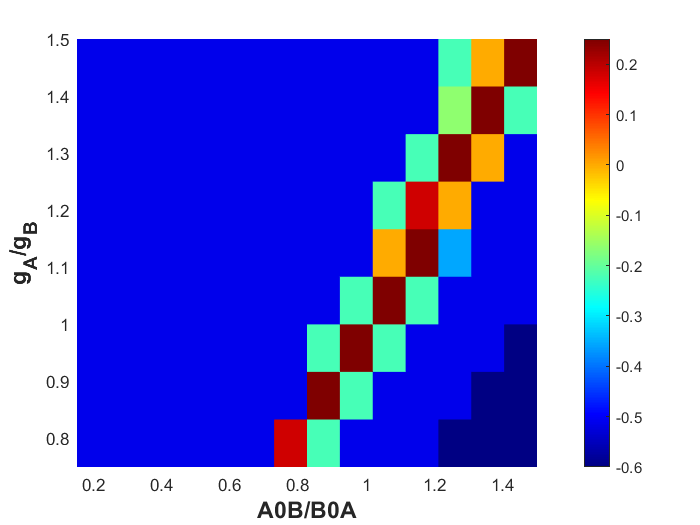

xlabel('A0B/B0A',"FontSize",14,"FontWeight","bold","FontName",'Arial')
ylabel('g_A/g_B',"FontSize",14,"FontWeight","bold","FontName",'Arial')

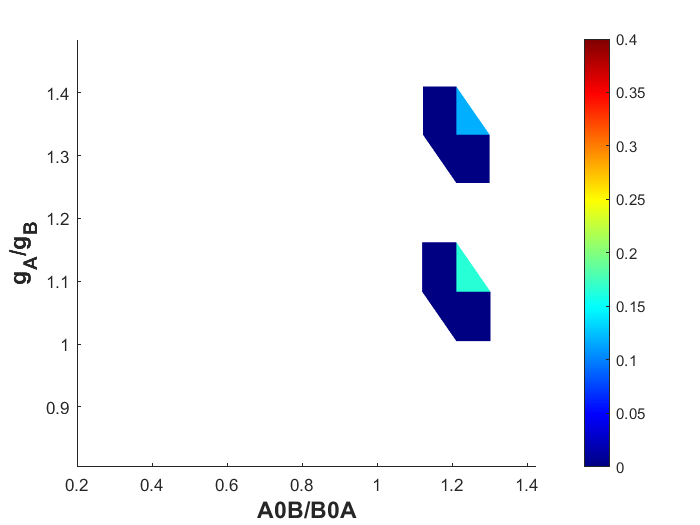

%title('Comparison of steady state time log(\mu(t)/100)')


c=cv_array ;
surf(A0B_array,g_array,cv_array,'EdgeColor','none'), colormap jet,grid off,caxis([0,0.4]), 
view([0.4 90.0])
ylim([min(g_array) max(g_array)])
xlim([min(A0B_array) max(A0B_array)])

colorbar
xlabel('A0B/B0A',"FontSize",14,"FontWeight","bold","FontName",'Arial')
ylabel('g_A/g_B',"FontSize",14,"FontWeight","bold","FontName",'Arial')

%title('Comparison of steady state time C.V ')

**Defining the local functions**

The domain length L and he decay coefficent mu is defined in the function for initialisation. 

function [c,f,s] = pde_fn_pde(x,t,u,DuDx,A,B,C,g_A,A0B)
c = [1; 1]; % c diagonal terms

f = [0.001; 0.001] .* DuDx; % diffusion term

s=interactions(t,u,g_A,A0B);
end

function [pl,ql,pr,qr] = pde_fn_bc(xl,ul,xr,ur,t,A,B,C,g_A,A0B)
pl = [0; 0];
ql = [1; 1];
pr = [0; 0];
qr = [1; 1];
end

function u0 = pde_fn_ic (x,A,B,C,g_A,A0B)
global mu % mu tells us how quickly and how much the concentraion decays
mu=5 ;

global L
L=0.5; % The Domain length L is defined in this line

u0 = [3+A*exp(-((x)*mu))+normrnd(0,1,size(x))
    3+A*exp(-((L-x)*mu))+normrnd(0,1,size(x))];
end



We define a function that returns the time taken to reach the steady state by the system

function t=time_for_ss(sol,x_divs,t_divs,t_max)
%This function expects a 2-D array of x and t axis
%We would be using two for loops

n=x_divs;
for i=1:t_divs
    curr_max=sol(i,1);
    curr_min=sol(i,1);
    for j=1:n
        
        if curr_min>sol(i,j)
            
            curr_min=sol(i,j);
            
        end
        
        if curr_max< sol(i,n-j+1)
            
            curr_max=sol(i,j);
            
        end
        
        if abs(curr_max-curr_min) > 0.01
            break;
           
        end
        
        
    end
    if abs(curr_max-curr_min)<0.01
        t=i*t_max/t_divs ;
        break;
    end
   
    
end
end


% hill function
function H = hill(X,X0,lambda,n)
% H+ 
H1 = (X^n)/(X0^n+X^n);
% H-
H2 = (X0^n)/(X0^n+X^n);

% Hill function =  H- plus (lambda)* H+
H = H2 + lambda*H1;

end


function dxdt = interactions(t,x,g_A,A0B)

% defining array of values for the time t: 
dxdt = zeros(2,1);

%% Paramaters
% Degradation rate:
gamma_A = 0.5;  
gamma_B = 0.5;  

% Transcription rate/ Production rate:
% g_A = 10; 
g_B = 10;   

% Hills function threshold :
% A0B = 10;
B0A = 2;
A0A = 10;   B0B = 10;

% Cooperativity/ hill function coefficient:
nAtoB = 5;   nBtoA = 5;
nAtoA = 3;   nBtoB = 3;

% fold change/ lambda
lambda_AtoB = 0.1;   lambda_BtoA = 0.1;
lambda_AtoA = 3;   lambda_BtoB = 3;

%% equations:
% dxdt(1) = g_A*hill(x(1),A0A,lambda_AtoA,nAtoA)*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
% dxdt(2) = g_B*hill(x(2),B0B,lambda_BtoB,nBtoB)*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
% end
dxdt(1) = g_A*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
dxdt(2) = g_B*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
end


